The code in this assignment was developed in collaboration with my group, group 23. Therefore there will be code that resembels theirs.

## Creating "clean" 1000Hz signal using Matlab

Setting up the parameters

% some parameters and preps
fs = 10000;             % sampling frequency
T = 10;                 % duration in seconds
n = randn(fs*T, 1);     % some random vector (white noise)

Identifying the length of the vector

% identify the length of the vector
len_n_samples = length(n);      % in samples
len_n_s = length(n) / fs;       % in time

Calculate the frequency vector

% calculate the frequency vector
T0 = length(n) / fs;            % duration of the signal in seconds
delta_f = 1 / T0;               % frequency resolution

Get the positive frequencies first

% get the positive frequencies first
f_pos = 0:delta_f:fs/2;         % positive frequencies up to fs/2 (Nyquist)
f_neg = -fs/2+delta_f:delta_f:-delta_f;  % negative frequencies from -fs/2 to 0

Now we calculate the spectrum of our signal

% Now we calculate the spectrum of our signal and plot it on a meaningful axis!
Y = fft(n);                     % Compute the FFT of the signal

Take only positive frequencies (single-sided spectrum)

% Take only positive frequencies (single-sided spectrum)
Y_pos = Y(1:floor(length(Y)/2) + 1);  % Only positive part of the spectrum

Plot the magnitude of the spectrum (in dB)

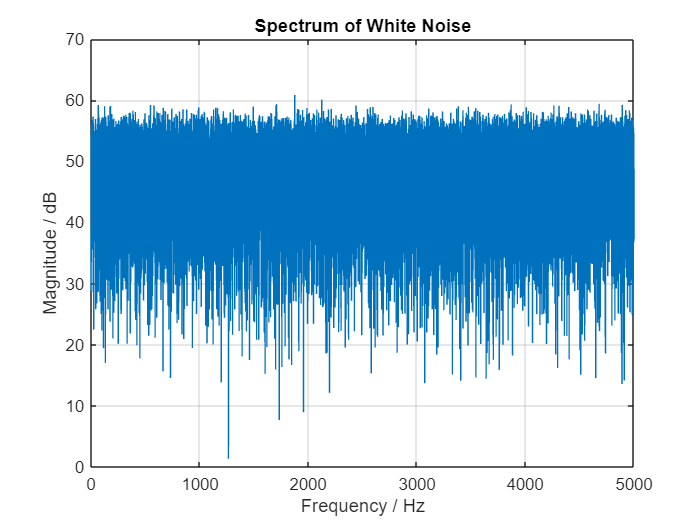

% Plot the magnitude of the spectrum (in dB)
figure;
plot(f_pos, 20*log10(abs(Y_pos)));
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Spectrum of White Noise');
grid on;

Generate and plot a sinusoidal signal

% Generate and plot a sinusoidal signal
[x_values, y_values] = generate_sinusoid(1, 1000, 0, fs, 0.5);

Call the make_spectrum function

[Y, freq] = make_spectrum(y_values, fs);

Plotting of 1000 Hz clean sinusoidal signal, using the stem function

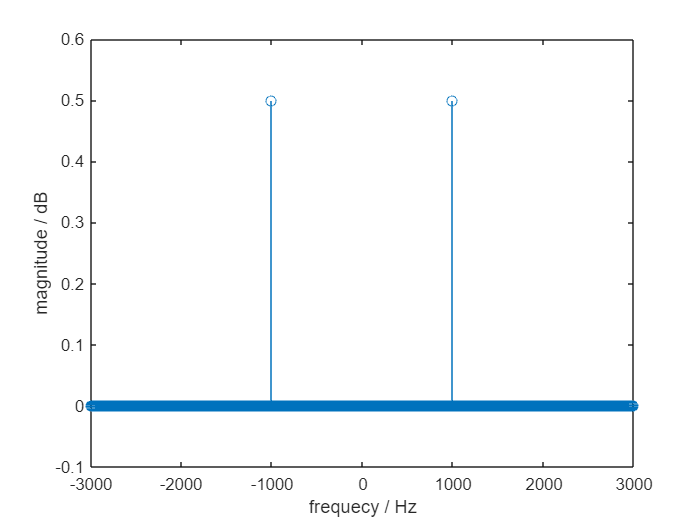

stem(freq, abs(Y))
xlabel('frequecy / Hz')
ylabel('magnitude / dB')

xlim([-3000 3000])
ylim([-0.100 0.600])

Ploting of the spectrum for the sinusoidal signal

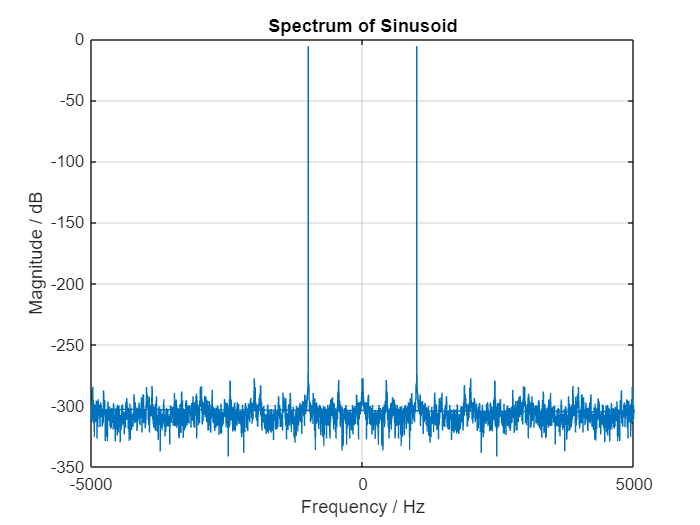

% Plot the spectrum for the sinusoidal signal
figure;
plot(freq, 20*log10(abs(Y)));
xlim([-fs/2 fs/2]);
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Spectrum of Sinusoid');
grid on;

## Analyzing recorded signal

Read .wav file

% Read your own .wav file
[signal, fs] = audioread('iii1000hz.wav');

If the signal is stereo, which ours is, convert it to mono by averaging the two channels

if size(signal, 2) == 2
    signal = mean(signal, 2);
end

Call the make_spectrum function

[Y, freq] = make_spectrum(signal(end-24000+1:end), fs); %end part makes sure that our samples are 2 Hz appart, since we take half of the signal 

Plotting the stem function

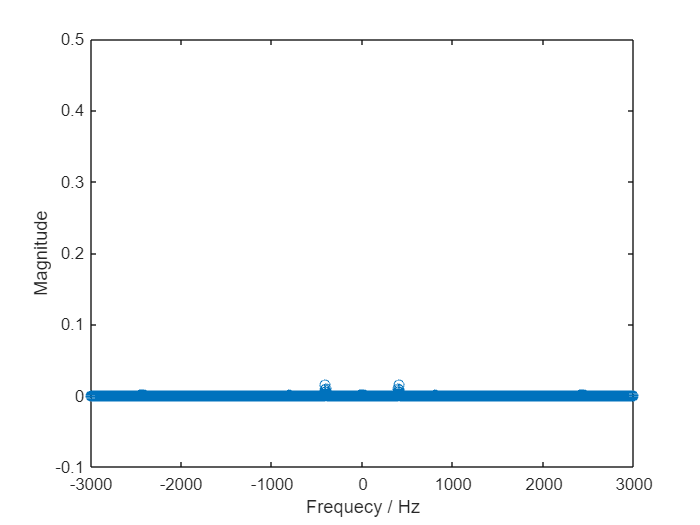

stem(freq, abs(Y))
xlim([-fs/2 fs/2])
xlabel('Frequecy / Hz')
ylabel('Magnitude')

xlim([-3000 3000])
ylim([-0.100 0.500])

Plot the magnitude spectrum of your recording

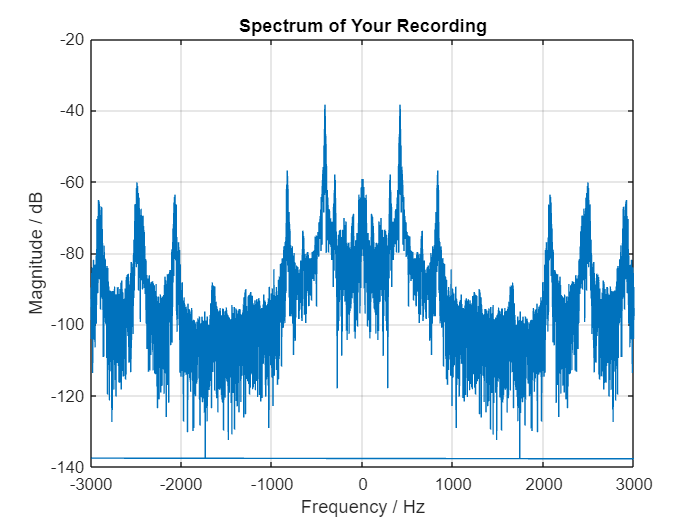

% Plot the magnitude spectrum of your recording
figure;
plot(freq, 20*log10(abs(Y)));
xlim([-3000 3000]);
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Spectrum of Your Recording');
grid on;

## Functions

Function to generate a sinusoid

function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    % Generates a sinusoidal signal
    time_vector = 0:1/fs:T_s-1/fs;  % Time vector (duration T_s)
    signal = a * cos(2 * pi * f * time_vector + phi);  % Sinusoidal signal
end

Function definition (spectrum calculation)

function [Y, freq] = make_spectrum(signal, fs)
    % Compute the FFT of the signal (complex-valued)
    Y = fft(signal);
    
    % Normalize the FFT by the length of the signal
    Y = Y / length(Y);    

    % Frequency resolution
    N = length(signal);           % Number of samples
    T0 = N / fs;                  % Duration of signal in seconds
    delta_f = 1 / T0;             % Frequency resolution

    % Frequency vector (positive and negative frequencies)
    if mod(N, 2) == 0
        % FOR EVEN NUMBER OF SAMPLES
        f_pos = 0:delta_f:fs/2;    % Positive frequencies up to fs/2
        f_neg = -fs/2+delta_f:delta_f:-delta_f; % Negative frequencies
    else
        % FOR ODD NUMBER OF SAMPLES
        f_pos = 0:delta_f:(floor(N/2) * delta_f); % Up to just below Nyquist
        f_neg = -(floor(N/2)) * delta_f:delta_f:-delta_f; % Negative frequencies
    end

    % Combine positive and negative frequencies
    freq = [f_pos f_neg];

    % Convert FFT result to decibels if needed
    % Y = 20 * log10(abs(Y));  % Optionally apply dB scale here

    % Convert to column vectors if necessary
    Y = Y(:);
    freq = freq(:);
end